# Homework 4 (Chapter 2)

**Name: Kyle Limbaga, Dawson Tocarchick, Nicholas Riggins**

## **Problem 1: **

Suppose you have a mechanical clock that has a minute hand, but no hour hand. Next, suppose you took a photograph of the clock when the minute hand was pointed at 12:00 noon and then took additional photos every 55 minutes. Upon showing those photos, in time order, to someone: (a) What would that person think about the direction of motion of the minute hand as time advances?

 (b) With the idea of lowpass sampling in mind, how often would you need to take photos, measured in photos/hour, so that the successive photos show proper (true) clockwise minute-hand rotation

Answer:

A) A person would think the clock is rotating in an anti clockwise direction

B) The Snapchots would need to be done every 30mins or less to have the photos look like there going in a clockwise direction. So you would need at least 2 samples per hour.

## **Problem 2:**

Assume we sampled a continuous x(t) signal and obtained 100 x(n) time-domain samples. What important information (parameter that we need to know in order to analyze x(t)) is missing from the x(n) sequence?

Answer:

The parameter we would still need to know is the sampling frequen?cy (Fs)

## **Problem 3:**

National Instruments Corporation produces an analog-to-digital (A/D) converter (Model #NI5154) that can sample (digitize) an analog signal at a sample rate of fs = 2.0 GHz (gigahertz). 

(a) What is the ts period of the output samples of such a device

 (b) Each A/D output sample is an 8-bit binary word (one byte), and the converter is able to store 256 million samples. What is the maximum time interval over which the converter can continuously sample an analog signal

Answer:

A) The period of the output samples is 0.5 ns

B) The maximum time interval is 79.5774 ps

## **Problem 4:**

Consider a continuous time-domain sinewave, whose cyclic frequency is 500 Hz, defined by x(t) = cos[2π(500)t + π/7]. Write the equation for the discrete x(n) sinewave sequence that results from sampling x(t) at an fs sample rate of 4000 Hz

Answer:


$$x\left\lbrack n\right\rbrack =\mathrm{cos}\left\lbrack \frac{27}{8}\pi n+\frac{\pi }{7}\right\rbrack$$


## **Problem 5:**

If we sampled a single continuous sinewave whose frequency is fo Hz, over what range must ts (the time between digital samples) be to satisfy the Nyquist criterion? Express that ts range in terms of fo.

Answer:

The range of ts must be $\mathrm{ts}<\frac{1}{2}\frac{1}{\mathrm{fo}}$

## **Problem 6:**

Suppose we used the following statement to describe the Nyquist criterion for lowpass sampling: “When sampling a single continuous sinusoid (a single analog tone), we must obtain no fewer than N discrete samples per continuous sinewave cycle.” What is the value of this integer N?

Answer:

This signal only contains 1 frequency and Nyquist criterion reconstructs the frequency at twice the frequency of the orginal signal. So the inreger value of N is 2.

## **Problem 7:**

The Nyquist criterion, regarding the sampling of lowpass signals, is sometimes stated as “The sampling rate fs must be equal to, or greater than, twice the highest spectral component of the continuous signal being sampled.” Can you think of how a continuous sinusoidal signal can be sampled in accordance with that Nyquist criterion definition to yield all zero-valued discrete samples

**Answer:**

If the signal was a continuous sinusoidal signal then in order for the sample to be in accordance with the Nyquist criterion definition and yield all zero-valued discrete samples, the sampling of the frequency has to be 2f

## **Problem 8:**

 Stock market analysts study time-domain charts (plots) of the closing price of stock shares. A typical plot takes the form of that in Figure P2-8, where instead of plotting discrete closing price sample values as dots, they draw straight lines connecting the closing price value samples. What is the ts period for such stock market charts? 

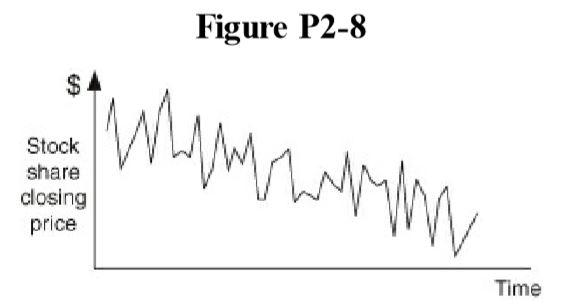

**Answer:**

Stock share closing prices are usually after 4:00 pm everyday for US market share so the ts period would 24 hours. 

## **Problem 9:**

Consider a continuous time-domain sinewave defined by 


$$x\left(t\right)=\mathrm{cos}\left(4000\pi t\right)$$


that was sampled to produce the discrete sinewave sequence defined by 


$$x\left(n\right)=\mathrm{cos}\left(n\frac{\pi }{2}\right)$$


What is the fs sample rate, measured in Hz, that would result in sequence x(n)? 

**Answer:**

fs = 2000

## **Problem 10:**

**Consider the two continuous signals defined by**

$a\left(t\right)=\mathrm{cos}\left(4000\pi t\right)$and $b\left(t\right)=\mathrm{cos}\left(200\pi t\right)$

whose product yields the x(t) signal shown in Figure P2-10. What is the minimum fs sample rate, measured in Hz, that would result in a sequence x(n) with no aliasing errors (no spectral replication overlap)? 

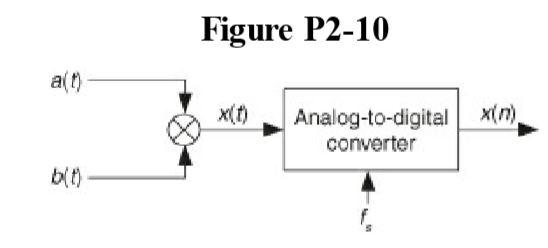

**Answer:**

The min fs sample rate in Hz would be 100.

Ta = 2pi/4000 = 1/2000 Tb = 1/100 LCM(Ta,Tb) = 100

## **Problem 11:**

 Consider a discrete time-domain sinewave sequence defined by


$$x\left(n\right)=\mathrm{sin}\left(n\frac{\pi }{4}\right)$$


that was obtained by sampling an analog x(t) = sin(2πfot) sinewave signal whose frequency is fo Hz. If the sample rate of x(n) is fs = 160 Hz, what are three possible positive frequency values, measured in Hz, for fo that would result in sequence x(n)? 

**Answer:**

fo = 20, 10, 6.66 Hz

omega = pi/4, N = 2pi/omega or 8 samples per cycle. N = 8k. 160/8 = 20, 160/16=10, 160/24 = 6.66

## **Problem 12:**

 In the text we discussed the notion of spectral folding that can take place when an xa(t) analog

signal is sampled to produce a discrete xd(n) sequence. We also stated that all of the analog spectral energy contained in Xa(f) will reside within the frequency range of ±fs/2 of the Xd(f) spectrum of the sampled xd(n) sequence. Given those concepts, consider the spectrum of an analog signal shown in Figure P2-12(a) whose spectrum is divided into the six segments marked as 1 to 6. Fill in the following table showing which of the A-to-F spectral segments of Xd(f), shown in Figure P2-12(b), are aliases of the 1-to-6 spectral segments of Xa(f).

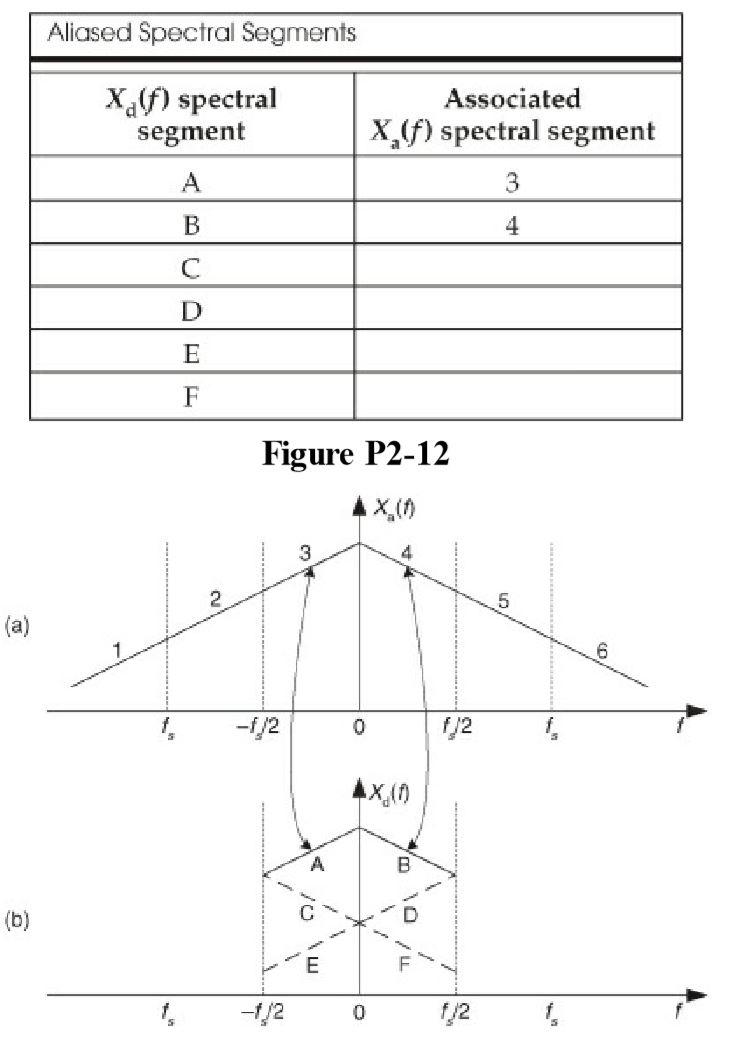

**Answer: **

C = 2

D = 5

E = 6

F = 1

## **Problem 13:**

**Here is a problem whose solution may be useful to you in the future. On the Internet you will find information suggesting that an inverse DFT can be computed using a forward DFT software routine in the process shown in Figure P3-13.**

**(A)**

**DFT:   **$X\left(k\right)=\sum_{n=0}^{N-1} {x_n e}^{\frac{-\mathrm{j2}\pi }{N}\mathrm{kn}}$

            
$$x\left(\omega \right)=\sum_{n=-\infty }^{\infty } x\left(n\right)\;e^{-j\omega n}$$


**IDFT: **$X\left(n\right)=\frac{1}{N}\sum_{m=0}^{N-1} {X\left(m\right)e}^{\frac{j\left(2\pi \mathrm{nm}\right)}{N}}$

           
$$x\left(n\right)=\frac{1}{N}\;\sum_{k\;=\;0}^{N-1} x\left(k\right)e^{\frac{\left(\mathrm{j2}\pi \mathrm{nk}\right)}{N}} \;$$


Complex Conjugate:


$$x\left(n\right)\longleftrightarrow x\left(-k*\mathrm{mod}\;N\right)$$



$$x\left(-n*\mathrm{mod}\;N\right)\longleftrightarrow x\left(k\right)$$


Proven through:

 
$$x\left(k\right)=x\left(-k*\mathrm{mod}\;N\right)$$



$$X\left(k\right)=\sum_{n=0}^{N-1} {x\left(n\right)e}^{\frac{-\mathrm{j2}\pi }{N}\left(-k\;\mathrm{modN}\right)n}$$


         
$$=\sum_{n=0}^{N-1} {x\left(n\right)e}^{\frac{-\mathrm{j2}\pi }{N}\left(\mathrm{kn}\right)}$$



$$X\left(-k\;\mathrm{mod}\;N\right)=X\left(k\right)$$


**(B)**

## **Problem 14:**

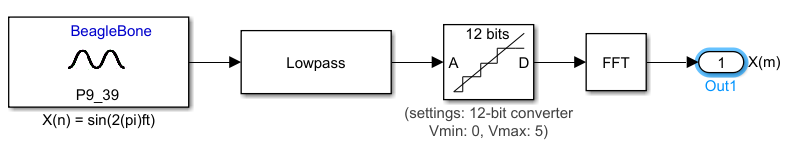

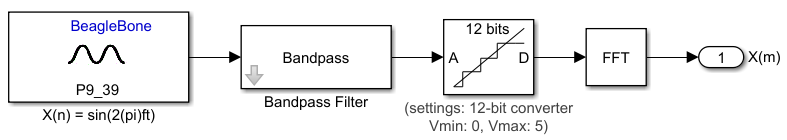

We can use sampling methods shown in chapter 2, such as lowpass filtering and Bandpass filtering.

## **Problem 15:**

**Unable to comprehend correctly, would appreciate example done in class**

## **Problem 16:**

clf
n = 1:47

n =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47


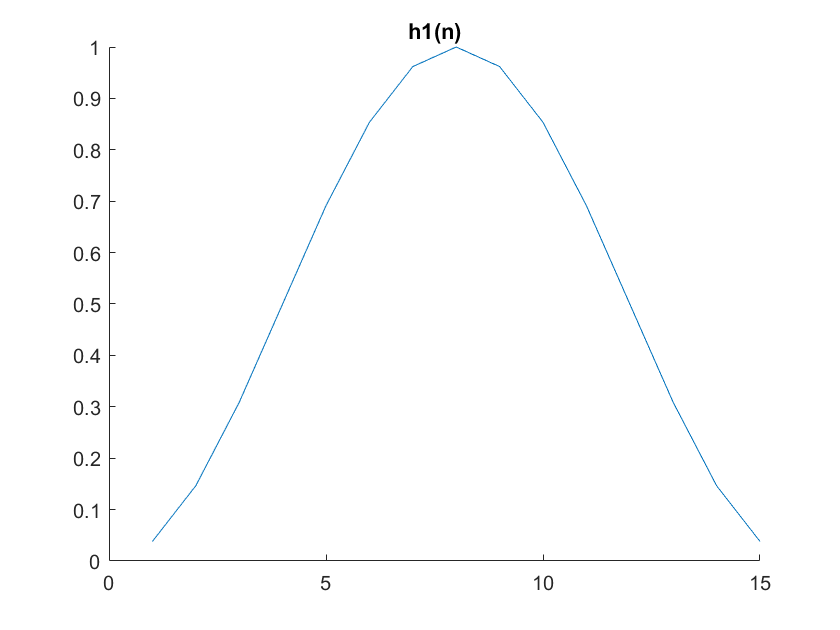

figure
for n = 1 : 15
    h1(n) = 0.5-.5*(cos((2*pi*n)/16));
    hold on
    plot(h1)
end
title("h1(n)")
hold off

**(A) **$h_1 \left(n\right)$ is made of two signals, a DC signal of 0.5, and a signal $-0\ldotp 5\;\mathrm{cos}\left(\frac{2\pi n}{16}\right)$. $h_1 \left(n\right)$ looks the way it does, because it has a positive component of 0.5 meaning the y value is offset by 0.5, and there is a frequency over time that is shifting up and down from 0 to 1 by subtracting the resultant of the signal.

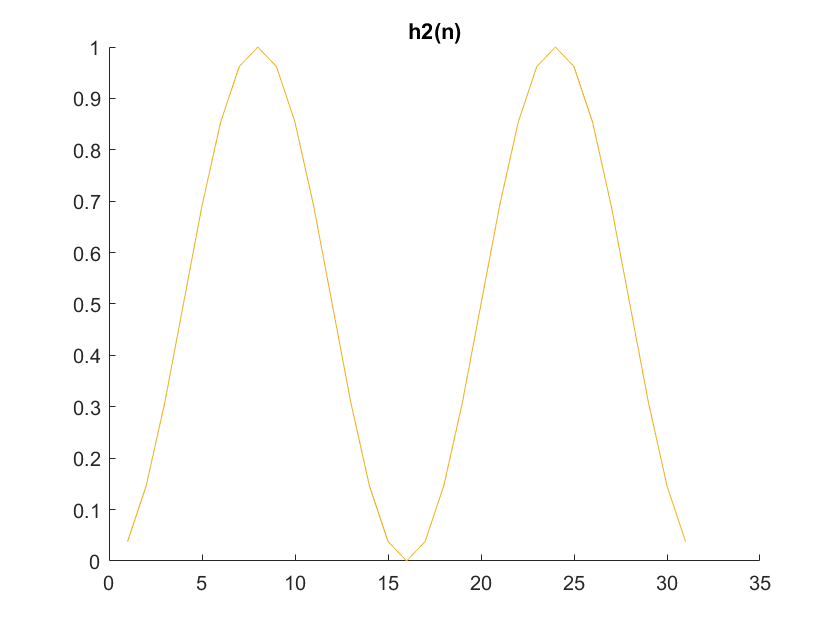

clf
figure
for n = 1 : 31
    h2(n) = .5 -.5*(cos((2*pi*n)/16));
    hold on
    plot(h2)
end
title("h2(n)")
hold off

**(B)**

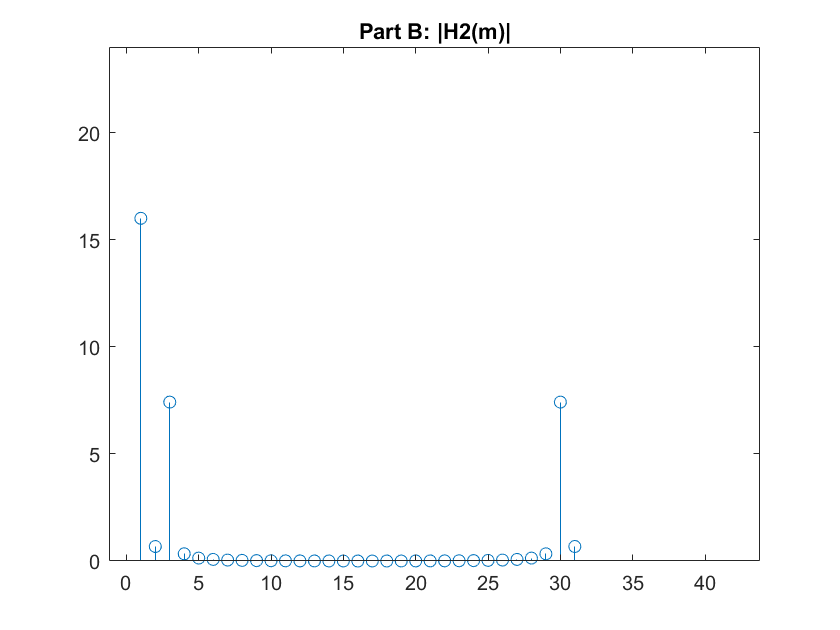

figure
f=abs(real(fft(h2)));
stem(1:31,f)
xlim([-1.2 43.8])
ylim([0.0 24.0])
title("Part B: |H2(m)|")

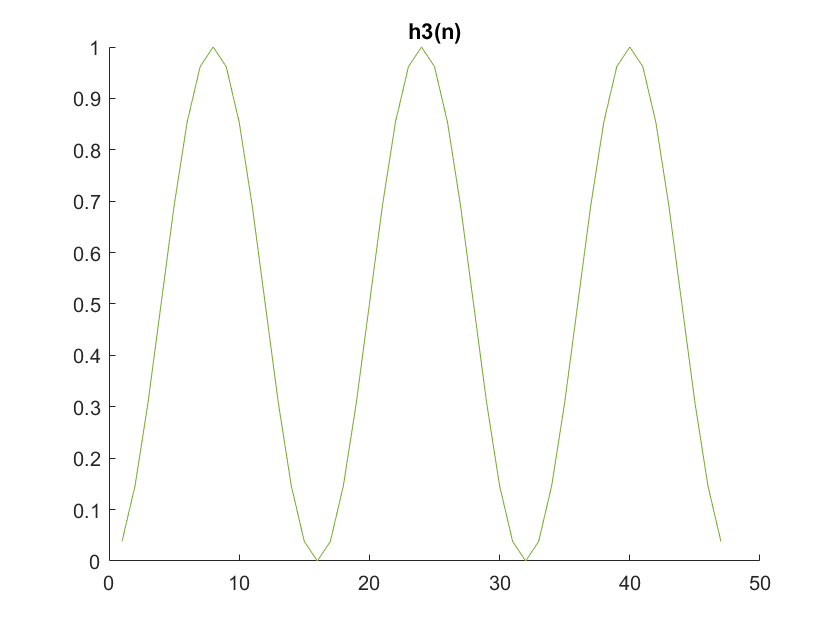

clf
figure
for n = 1 : 47
    h3(n) = .5 -.5*(cos((2*pi*n)/16));
    hold on
    plot(h3)
end
title("h3(n)")
hold off

**(C)**

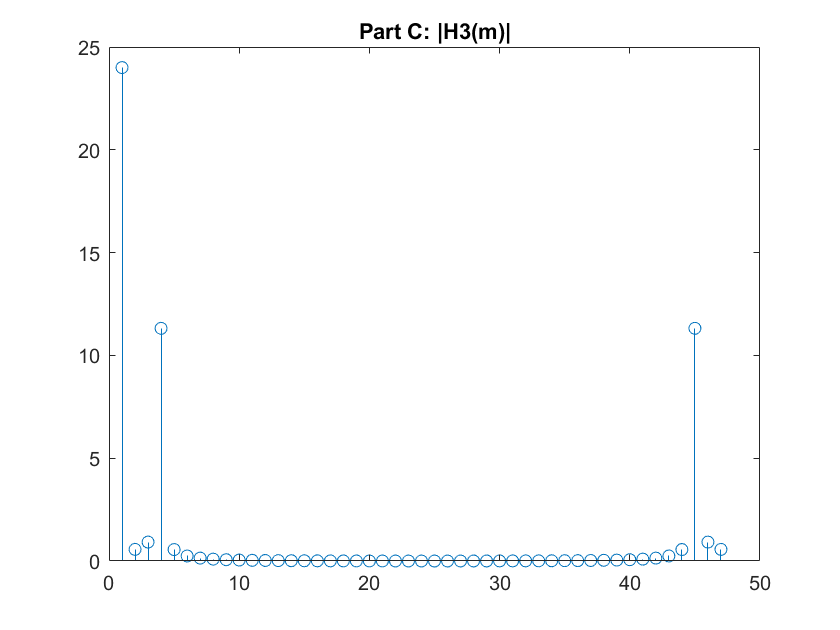

figure
f=abs(real(fft(h3)));
stem(1:47,f)
title("Part C: |H3(m)|")

**(D)**

**“K repetitions of an h1(n) sequence result in an extended-length time sequence whose spectral magnitudes have K−1 ...”**

**            GAIN**

## **Problem 18:**

A Continuous fourier transform is performed in which there are a number of padded zeros in the data. The transform creates a centered wave form, where as Q increases the observer will see graphical points that resemble the wave itself.

## **Problem 20:**

SNR_N = 10*log(1000000/100)

SNR_N = 92.1034

Gain of 92.103 in their signal